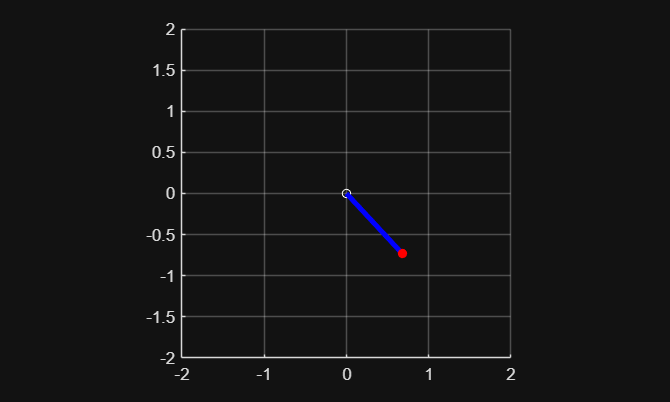

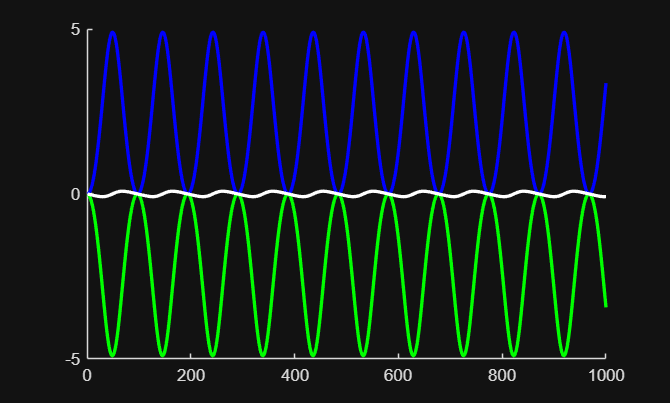

clear all;

figure;
axis([-2 2 -2 2]);
axis square;
grid on;
hold on;

% Parameters
g = 9.81;
L = 1;
b = 0;
dt = 0.01; % timestep (seconds)

% Initial conditions
theta = pi/2;
omega = 0;

% setup handles
pivot = plot(0, 0, 'wo', 'MarkerSize', 5);
rod = plot([0, L*sin(theta)], [0, -L*cos(theta)], 'b-', 'LineWidth', 3);
bob = plot(L*sin(theta), -L*cos(theta), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'red');
trail = plot(NaN, NaN, 'r--', 'LineWidth', 1);

trail_x = [];
trail_y = [];
N = 100;

figure;
k = animatedline('Color', 'b', 'LineWidth', 2);
gp = animatedline('Color', 'g', 'LineWidth', 2);
total = animatedline('Color', 'w', 'LineWidth', 2);
E = 0;
KE = 0;
GPE = 0;

for i = 1:1000
    tic;

    GPE = g * -(L/2)*cos(theta);
    KE = (1/2) * (1/3)*L^2 * omega^2;
    E = GPE + KE;

    alpha = -(3*g*sin(theta))/(2*L) - b*omega;
    omega = omega + alpha * dt;
    theta = theta + omega * dt;

    rod.XData = [0, L*sin(theta)];
    rod.YData = [0, -L*cos(theta)];
    bob.XData = L*sin(theta);
    bob.YData = -L*cos(theta);

    drawnow;
    
    % Pause only for the remaining time in this timestep
    elapsed = toc;
    remaining = dt - elapsed;
    if remaining > 0
        pause(remaining);
    end
    % addpoints(h, i, E);
    addpoints(k, i, KE);
    addpoints(gp, i, GPE);
    addpoints(total, i, E);
end